# Course Project: Detecting Valid Coins and Counting

## Project Tasks

There are four main stages in the workflow: 

1. Segmenting the foreground (coins and blanks) from the background 

2. Detecting and isolating valid coin faces 

3. Segmenting only valid coins 

4. Counting the number of each coin and calculating the total $ value 

## 1. Segment the Foreground

For this problem you will be assessed using a randomly chosen selection from the three test images, so it is a good idea to test your algorithm on each of them in MATLAB before submitting here. 

- Your code will need to create a mask to accurately segment the foreground (both the coins and blanks) from the background. Use variable name `testCoinMask`.

- Depending on how you segmented the image with all valid coins, the same code may work here, but you'll need to test it to be sure. 

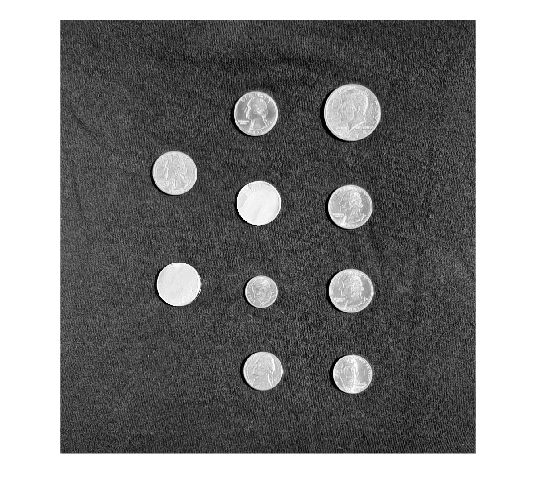

testImageIdx = randi([1,3]);
testCoinImage = imread("testCoinImage"+testImageIdx+".png");
figure, imshow(testCoinImage)

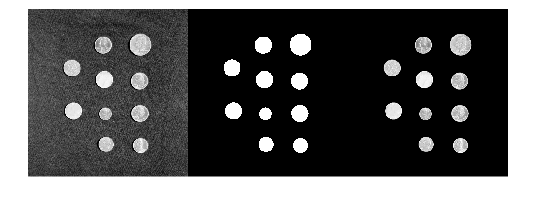


[testMask, maskedTestCoinImage] = segmentImageFun(testCoinImage);
montage({testCoinImage, testMask, maskedTestCoinImage}, "Size",[1 3])

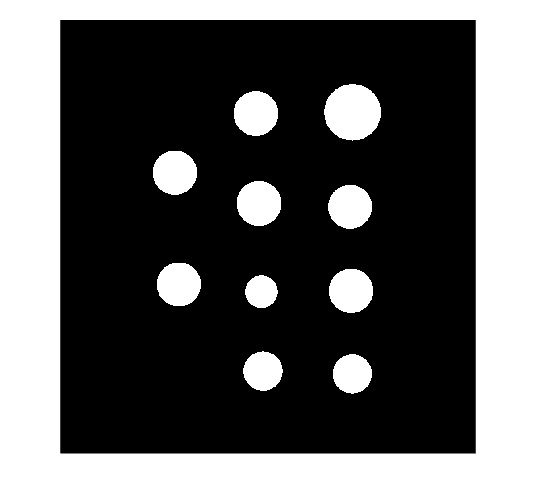


imshow(testMask)

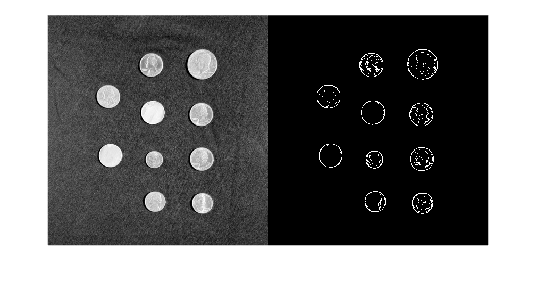

function [BW,maskedImage] = segmentImageFun(X)
%segmentImage Segment image using auto-generated code from Image Segmenter app
%  [BW,MASKEDIMAGE] = segmentImage(X) segments image X using auto-generated
%  code from the Image Segmenter app. The final segmentation is returned in
%  BW, and a masked image is returned in MASKEDIMAGE.

% Auto-generated by imageSegmenter app on 24-Jul-2024
%----------------------------------------------------



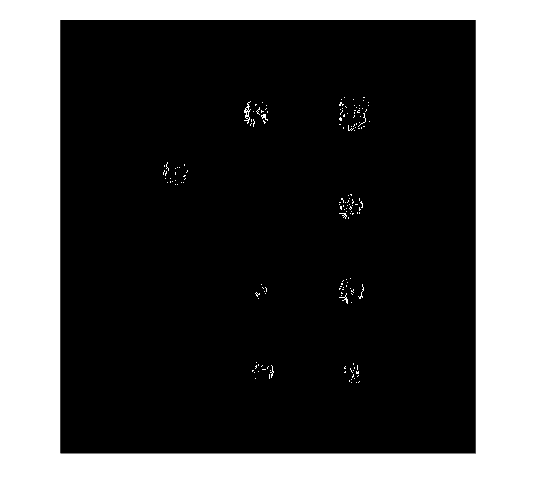

% Find circles
[centers,radii,~] = imfindcircles(X,[25 75],'ObjectPolarity','bright','Sensitivity',0.90);
max_num_circles = Inf;

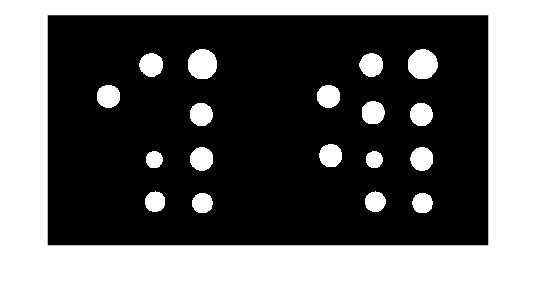

if max_num_circles < length(radii)
    centers = centers(1:max_num_circles,:);
    radii = radii(1:max_num_circles);
end
BW = circles2mask(centers,radii,size(X,1:2));

% Create masked image.
maskedImage = X;

maskedImage(~BW) = 0;
end

## 2. Valid Coin Face Edges

A major feature that distinguishes the valid coins from the blanks is that valid coins have more pronounced edges closer to the center. Below is an example of edges (found using the `edge` function) overlayed on one of the quarters vs. one of the blanks.  

For this problem your code will need to create a mask which only includes true pixels for all valid coin regions. That is, you need to end up with *true pixels in the interior of each valid coin, but nowhere else*. Use variable name `faceEdgeMask`. 

One workflow to accomplish this is given below:

- Use the `edge` function to create a binary image showing many edges on the coins, and few to no edges on the surface of the blanks. **NOTE:** The background of the original image is not smooth. Background edges could bias an automatically chosen edge threshold. You may find it advantageous to use the masked foreground image for your edge calculations. 

- Eliminate the pixels in the edge mask other than those in the valid coins. Remember, you should have true pixels in your edge mask distributed into the center of the coins, while you have no true pixels other than near the outer rim of the blanks. Logically combining your edge mask with an eroded version of your foreground segmentation mask should leave you with only the edges closer to the coin centers. 

se = strel('disk', 20, 0);
testMask = testCoinMask;
testMask = imfill(testMask, 'holes');
testMask = imerode(testMask, se);

%imgFilt = imgaussfilt(maskedTestCoinImage, 0.5, Padding="circular", FilterDomain="frequency", FilterSize=3);
%faceEdgeMask = edge(imgFilt, "sobel", "nothinning");

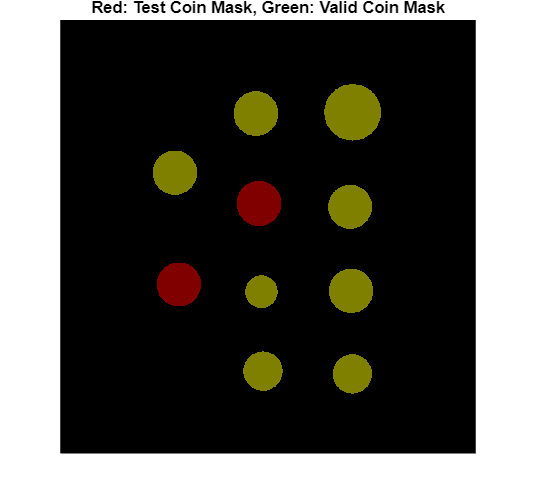

faceEdgeMask = edge(maskedTestCoinImage, "sobel", "nothinning");
montage({testCoinImage, faceEdgeMask})


faceEdgeMask(~testMask) = false;
imshow(faceEdgeMask);

## 3. Valid Coin Segmentation

For this problem your code will need to create a mask which completely segments *only* the valid coins. Use the variable name `validCoinMask`. 

The solutions to the previous assignments include a foreground mask with true pixel regions where any circular object is present (`testCoinMask`), and another coin face edge mask with true pixels only within the regions of valid coins (`faceEdgeMask`). Therefore, one approach to this task is to dilate the true pixel regions in `faceEdgeMask` to be greater than or equal to the size of the corresponding foreground regions in `testCoinMask`, and logically combine the result with `testCoinMask` to extract the valid coin regions. **NOTE:** Be careful not to dilate so far you overlap regions for blanks in the foreground mask.

se = strel("disk",40,0);

coinSizes = 8×2 table
    Area     Perimeter
    _____    _________

     7750     309.19  
     7920      312.2  
     6060     273.25  
     4180     226.24  
    12603     395.55  
     7589     305.45  
     7771     309.49  
     6050     273.25  


validCoinMask = imdilate(faceEdgeMask,se);
validCoinMask = validCoinMask & testCoinMask;
montage({validCoinMask, testCoinMask})

 %Create a colored representation of the masks
coloredTestCoinMask = cat(3, testCoinMask, zeros(size(testCoinMask)), zeros(size(testCoinMask))); % Red
coloredValidCoinMask = cat(3, zeros(size(validCoinMask)), validCoinMask, zeros(size(validCoinMask))); % Green

% Combine the two masks
combinedMask = imfuse(coloredTestCoinMask, coloredValidCoinMask, 'blend');


USD = 1.7000

% Display the combined mask
figure;
imshow(combinedMask);
title('Red: Test Coin Mask, Green: Valid Coin Mask');

## 4. Counting Valid Coins

For this problem your code will need to do the following: 

- Accurately determine the number of each coin type present. Use variable names `nDimes`, `nNickels`, `nQuarters`, and `nFiftyCents`. 

- Calculate the total $ value of coins present. Use variable name `USD`. 

coinSizes = regionprops("table", validCoinMask, "Area", "Perimeter")
nDimes = coinSizes.Area < 4500;
nDimes = sum(nDimes);
nNickels = (coinSizes.Area > 4500 & coinSizes.Area <7000);
nNickels = sum(nNickels);
nQuarters = (coinSizes.Area > 7000 & coinSizes.Area < 9000);
nQuarters = sum(nQuarters);
nFiftyCents = coinSizes.Area > 9000;
nFiftyCents = sum(nFiftyCents);
USD = (nDimes * 0.10) + (nNickels * 0.05) + ... 
    (nQuarters * 0.25) + (nFiftyCents * 0.50)